# Generating the impact map for the three-link 2D biped (Assignment 2, continued)

Once the biped completes a step, the swing foot hits the ground and afterwards the swing leg becomes the **new** stance leg and the stance leg becomes the **new** swing leg.  The **impact map,** which this scripts generates, defines such a transition. Indeed, the impact map, maps the state of the robot right before the impact to its state right after the impact. Mathematically, **assuming the impact and switching of the legs roles is instantenous**, we have 


$$\Delta(q^-, \dot q^-) = (q^+, \dot q^+)$$


where $(q^-, \dot q^-)$ is the state of the robot right before the impact and $(q^+, \dot q^+)$ denotes its state right after the impact. This script generates the impact map $\Delta$. 

**Note**: In this script we use the notation [q1_m, q2_m, q3_m] for $q^-$ and [q1_p, q2_p, q3_p] for $q^+$. Similarly, we use [dq1_m, dq2_m, dq3_m] for $\dot q^-$ and [dq1_p, dq2_p, dq3_p] for $\dot q^+$.

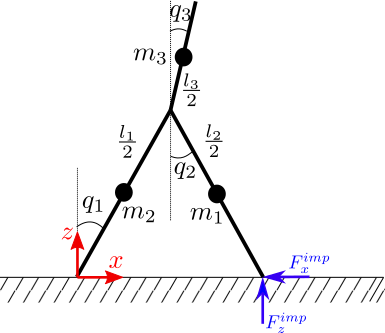

## Angles:

We can write the impact map as:


$$\Delta(q^-, \dot q^-) = (\Delta_q(q^-), \Delta_{\dot q} (q^-, \dot q^-))$$


This is true, because before and after impact the configuration of the robot (not the velocites) remains the same. So, for $\Delta_q$ all you need is to **swap** the indices of the stance and swing legs appropriately, taking into account that we always use index 1 for the stance leg and index 2 for the swing leg. You will be doing this directly in the impact.m function. 

syms q1_m q2_m q3_m q1_p q2_p q3_p

## Angular Velocities:

Unlike angles, which only needed bookeeping, calculation of angular velocities (i.e., $\dot q^+$) needs some physics. We will follow the approach of [McGeer 1988](https://aerovel.com/wp-content/uploads/2015/03/Stability-and-control-of-two-dimensional-bipedal-walking.pdf), i.e. method of **conservation of angular momentum** to calculate the angular velocities after impact. 

In the following cells you need the symbolic outputs of generate_kinematics. So, we first run generate_kinematics:

**Note: Before running generate_kinematics,** **update it to include velocities of (x_h, z_h) and (x_swf, z_swf) that is (dx_h, dz_h) and (dx_swf, dz_swf). Later we will be using them.** 

%load 'D:\Matlab\Leggedrobots\Prat2\three_link_biped_start\generate_model\generate_kinematics'

For the calculation of angular momentum before and after impact you first need to calculate the positions and velocites of the masses $m_1$, $m_2$ and $m_3$ as well as the hip joint before and after impact.

**Positions and velocities of the masses and the hip joint before the impact:**

syms dq1_m dq2_m dq3_m dq1_p dq2_p dq3_p
z1_m = (l1/2)*cos(q1_m)

$$z1\_m = \frac{l_{1}\,\cos\left(q_{1,m}\right)}{2}$$

x2_m = (l1)*sin(q1_m) + (l2/2)*sin(-q2_m)

$$x2\_m = l_{1}\,\sin\left(q_{1,m}\right)-\frac{l_{2}\,\sin\left(q_{2,m}\right)}{2}$$

x1_m = (l1/2)*sin(q1_m)

$$x1\_m = \frac{l_{1}\,\sin\left(q_{1,m}\right)}{2}$$

z2_m = (l1)*cos(q1_m) - (l2/2)*cos(-q2_m)

$$z2\_m = l_{1}\,\cos\left(q_{1,m}\right)-\frac{l_{2}\,\cos\left(q_{2,m}\right)}{2}$$

x3_m = (l1)*sin(q1_m) + (l3/2)*sin(q3_m)

$$x3\_m = l_{1}\,\sin\left(q_{1,m}\right)+\frac{l_{3}\,\sin\left(q_{3,m}\right)}{2}$$

z3_m = (l1)*cos(q1_m) + (l3/2)*cos(q3_m)

$$z3\_m = l_{1}\,\cos\left(q_{1,m}\right)+\frac{l_{3}\,\cos\left(q_{3,m}\right)}{2}$$

xh_m = (l1)*sin(q1_m)

$$xh\_m = l_{1}\,\sin\left(q_{1,m}\right)$$

zh_m = (l1)*cos(q1_m)

$$zh\_m = l_{1}\,\cos\left(q_{1,m}\right)$$

xswf_m = (l1)*sin(q1_m) + (l2)*sin(-q2_m)

$$xswf\_m = l_{1}\,\sin\left(q_{1,m}\right)-l_{2}\,\sin\left(q_{2,m}\right)$$

zswf_m = (l1)*cos(q1_m) - (l2)*cos(-q2_m)

$$zswf\_m = l_{1}\,\cos\left(q_{1,m}\right)-l_{2}\,\cos\left(q_{2,m}\right)$$

% 
dx1_m = diff(x1_m, q1_m)*dq1_m

$$dx1\_m = \frac{{\mathrm{dq}}_{1,m}\,l_{1}\,\cos\left(q_{1,m}\right)}{2}$$

dz1_m = diff(z1_m, q1_m)*dq1_m

$$dz1\_m = -\frac{{\mathrm{dq}}_{1,m}\,l_{1}\,\sin\left(q_{1,m}\right)}{2}$$

dx2_m = diff(x2_m, q1_m)*dq1_m + diff(x2_m, q2_m)*dq2_m

$$dx2\_m = {\mathrm{dq}}_{1,m}\,l_{1}\,\cos\left(q_{1,m}\right)-\frac{{\mathrm{dq}}_{2,m}\,l_{2}\,\cos\left(q_{2,m}\right)}{2}$$

dz2_m = diff(z2_m, q1_m)*dq1_m + diff(z2_m, q2_m)*dq2_m

$$dz2\_m = \frac{{\mathrm{dq}}_{2,m}\,l_{2}\,\sin\left(q_{2,m}\right)}{2}-{\mathrm{dq}}_{1,m}\,l_{1}\,\sin\left(q_{1,m}\right)$$

dx3_m = diff(x3_m, q1_m)*dq1_m + diff(x3_m, q3_m)*dq3_m

$$dx3\_m = {\mathrm{dq}}_{1,m}\,l_{1}\,\cos\left(q_{1,m}\right)+\frac{{\mathrm{dq}}_{3,m}\,l_{3}\,\cos\left(q_{3,m}\right)}{2}$$

dz3_m = diff(z3_m, q1_m)*dq1_m + diff(z3_m, q3_m)*dq3_m

$$dz3\_m = -{\mathrm{dq}}_{1,m}\,l_{1}\,\sin\left(q_{1,m}\right)-\frac{{\mathrm{dq}}_{3,m}\,l_{3}\,\sin\left(q_{3,m}\right)}{2}$$

dxh_m = diff(xh_m, q1_m)*dq1_m

$$dxh\_m = {\mathrm{dq}}_{1,m}\,l_{1}\,\cos\left(q_{1,m}\right)$$

dzh_m = diff(zh_m, q1_m)*dq1_m

$$dzh\_m = -{\mathrm{dq}}_{1,m}\,l_{1}\,\sin\left(q_{1,m}\right)$$

dxswf_m = diff(xswf_m, q1_m)*dq1_m + diff(xswf_m, q2_m)*dq2_m

$$dxswf\_m = {\mathrm{dq}}_{1,m}\,l_{1}\,\cos\left(q_{1,m}\right)-{\mathrm{dq}}_{2,m}\,l_{2}\,\cos\left(q_{2,m}\right)$$

dzswf_m = diff(zswf_m, q1_m)*dq1_m + diff(zswf_m, q2_m)*dq2_m

$$dzswf\_m = {\mathrm{dq}}_{2,m}\,l_{2}\,\sin\left(q_{2,m}\right)-{\mathrm{dq}}_{1,m}\,l_{1}\,\sin\left(q_{1,m}\right)$$

**Positions and velocities of the masses and the hip joint after the impact:**

z1_p = (l1/2)*cos(-q1_p)

$$z1\_p = \frac{l_{1}\,\cos\left(q_{1,p}\right)}{2}$$

x2_p = -(l1)*sin(-q1_p)-(l2/2)*sin(q2_p)

$$x2\_p = l_{1}\,\sin\left(q_{1,p}\right)-\frac{l_{2}\,\sin\left(q_{2,p}\right)}{2}$$

x1_p = -(l1/2)*sin(-q1_p)

$$x1\_p = \frac{l_{1}\,\sin\left(q_{1,p}\right)}{2}$$

z2_p = l1*cos(-q1_p)-(l2/2)*cos(q2_p)

$$z2\_p = l_{1}\,\cos\left(q_{1,p}\right)-\frac{l_{2}\,\cos\left(q_{2,p}\right)}{2}$$

x3_p = -(l1)*sin(-q1_p)+(l3/2)*sin(q3_p)

$$x3\_p = l_{1}\,\sin\left(q_{1,p}\right)+\frac{l_{3}\,\sin\left(q_{3,p}\right)}{2}$$

z3_p = (l1)*cos(-q1_p)+(l3/2)*cos(q3_p)

$$z3\_p = l_{1}\,\cos\left(q_{1,p}\right)+\frac{l_{3}\,\cos\left(q_{3,p}\right)}{2}$$

xh_p = -l1*sin(-q1_p)

$$xh\_p = l_{1}\,\sin\left(q_{1,p}\right)$$

zh_p = l1*cos(-q1_p)

$$zh\_p = l_{1}\,\cos\left(q_{1,p}\right)$$

xswf_p = -(l1)*sin(-q1_p)-(l2)*sin(q2_p)

$$xswf\_p = l_{1}\,\sin\left(q_{1,p}\right)-l_{2}\,\sin\left(q_{2,p}\right)$$

zswf_p = l1*cos(-q1_p)-(l2)*cos(q2)

$$zswf\_p = l_{1}\,\cos\left(q_{1,p}\right)-l_{2}\,\cos\left(q_{2}\right)$$

% 
dx1_p = diff(x1_p, q1_p)*dq1_p

$$dx1\_p = \frac{{\mathrm{dq}}_{1,p}\,l_{1}\,\cos\left(q_{1,p}\right)}{2}$$

dz1_p = diff(z1_p, q1_p)*dq1_p

$$dz1\_p = -\frac{{\mathrm{dq}}_{1,p}\,l_{1}\,\sin\left(q_{1,p}\right)}{2}$$

dx2_p = diff(x2_p, q1_p)*dq1_p + diff(x2_p, q2_p)*dq2_p

$$dx2\_p = {\mathrm{dq}}_{1,p}\,l_{1}\,\cos\left(q_{1,p}\right)-\frac{{\mathrm{dq}}_{2,p}\,l_{2}\,\cos\left(q_{2,p}\right)}{2}$$

dz2_p = diff(z2_p, q1_p)*dq1_p + diff(z2_p, q2_p)*dq2_p

$$dz2\_p = \frac{{\mathrm{dq}}_{2,p}\,l_{2}\,\sin\left(q_{2,p}\right)}{2}-{\mathrm{dq}}_{1,p}\,l_{1}\,\sin\left(q_{1,p}\right)$$

dx3_p = diff(x3_p, q1_p)*dq1_p + diff(x3_p, q3_p)*dq3_p

$$dx3\_p = {\mathrm{dq}}_{1,p}\,l_{1}\,\cos\left(q_{1,p}\right)+\frac{{\mathrm{dq}}_{3,p}\,l_{3}\,\cos\left(q_{3,p}\right)}{2}$$

dz3_p = diff(z3_p, q1_p)*dq1_p + diff(z3_p, q3_p)*dq3_p

$$dz3\_p = -{\mathrm{dq}}_{1,p}\,l_{1}\,\sin\left(q_{1,p}\right)-\frac{{\mathrm{dq}}_{3,p}\,l_{3}\,\sin\left(q_{3,p}\right)}{2}$$

dxh_p = diff(xh_p, q1_p)*dq1_p

$$dxh\_p = {\mathrm{dq}}_{1,p}\,l_{1}\,\cos\left(q_{1,p}\right)$$

dzh_p = diff(zh_p, q1_p)*dq1_p

$$dzh\_p = -{\mathrm{dq}}_{1,p}\,l_{1}\,\sin\left(q_{1,p}\right)$$

dxswf_p = diff(xswf_p, q1_p)*dq1_p + diff(xswf_p, q2_p)*dq2_p

$$dxswf\_p = {\mathrm{dq}}_{1,p}\,l_{1}\,\cos\left(q_{1,p}\right)-{\mathrm{dq}}_{2,p}\,l_{2}\,\cos\left(q_{2,p}\right)$$

dzswf_p = diff(zswf_p, q1_p)*dq1_p + diff(zswf_p, q2_p)*dq2_p

$$dzswf\_p = -{\mathrm{dq}}_{1,p}\,l_{1}\,\sin\left(q_{1,p}\right)$$

Positions and velocites before and after impact in vector form:

r1_m = [x1_m; z1_m];
r2_m = [x2_m; z2_m];
r3_m = [x3_m; z3_m];
rh_m = [xh_m; zh_m];
rswf_m = [xswf_m; zswf_m];
r1_p = [x1_p; z1_p];
r2_p = [x2_p; z2_p];
r3_p = [x3_p; z3_p];
rh_p = [xh_p; zh_p];
rswf_p = [xswf_p; zswf_p];
dr1_m = [dx1_m; dz1_m];
dr2_m = [dx2_m; dz2_m];
dr3_m = [dx3_m; dz3_m];
drh_m = [dxh_m; dzh_m];
drswf_m = [dxswf_m; dzswf_m];
dr1_p = [dx1_p; dz1_p];
dr2_p = [dx2_p; dz2_p];
dr3_p = [dx3_p; dz3_p];
drh_p = [dxh_p; dzh_p];
drswf_p = [dxswf_p; dzswf_p];

% we define this function to calcuate the cross products of 2d vectors.
 cross2d = @(v1, v2) (v1(1) * v2(2) - v2(1) * v1(2));

## Calculate angular momentums before and after impact:

We calculate the required angular momentums (as disscussed in the class) before and after impact around the swing foot end and the hip joint. 

 syms m m3 % note m1 = m2 = m
Ha_m = m1*cross2d(r1_m-rswf_m,dr1_m) + m2*cross2d(r2_m-rswf_m,dr2_m) + m3*cross2d(r3_m-rswf_m,dr3_m) % total angular momentum around the swing foot before impact 

$$Ha\_m = \begin{array}{l} m_{1}\,\left(\frac{{\mathrm{dq}}_{1,m}\,l_{1}\,\cos\left(q_{1,m}\right)\,\left(\frac{l_{1}\,\cos\left(q_{1,m}\right)}{2}-l_{2}\,\cos\left(q_{2,m}\right)\right)}{2}+\frac{{\mathrm{dq}}_{1,m}\,l_{1}\,\sin\left(q_{1,m}\right)\,\left(\frac{l_{1}\,\sin\left(q_{1,m}\right)}{2}-l_{2}\,\sin\left(q_{2,m}\right)\right)}{2}\right)-m_{2}\,\left(\frac{l_{2}\,\cos\left(q_{2,m}\right)\,\left(\sigma_{2}-\frac{{\mathrm{dq}}_{2,m}\,l_{2}\,\cos\left(q_{2,m}\right)}{2}\right)}{2}+\frac{l_{2}\,\sin\left(q_{2,m}\right)\,\left(\sigma_{1}-\frac{{\mathrm{dq}}_{2,m}\,l_{2}\,\sin\left(q_{2,m}\right)}{2}\right)}{2}\right)-m_{3}\,\left(\left(\sigma_{2}+\frac{{\mathrm{dq}}_{3,m}\,l_{3}\,\cos\left(q_{3,m}\right)}{2}\right)\,\left(l_{2}\,\cos\left(q_{2,m}\right)+\frac{l_{3}\,\cos\left(q_{3,m}\right)}{2}\right)+\left(\sigma_{1}+\frac{{\mathrm{dq}}_{3,m}\,l_{3}\,\sin\left(q_{3,m}\right)}{2}\right)\,\left(l_{2}\,\sin\left(q_{2,m}\right)+\frac{l_{3}\,\sin\left(q_{3,m}\right)}{2}\right)\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{dq}}_{1,m}\,l_{1}\,\sin\left(q_{1,m}\right)\\ \sigma_{2}={\mathrm{dq}}_{1,m}\,l_{1}\,\cos\left(q_{1,m}\right) \end{array}$$

Ha_p = m1*cross2d(r1_p,dr1_p) + m2*cross2d(r2_p,dr2_p) + m3*cross2d(r3_p,dr3_p) % total angular momentum around the now stance foot (after impact)

$$Ha\_p = \begin{array}{l} -m_{2}\,\left(\left(\sigma_{2}-\frac{{\mathrm{dq}}_{2,p}\,l_{2}\,\cos\left(q_{2,p}\right)}{2}\right)\,\left(l_{1}\,\cos\left(q_{1,p}\right)-\frac{l_{2}\,\cos\left(q_{2,p}\right)}{2}\right)+\left(\sigma_{1}-\frac{{\mathrm{dq}}_{2,p}\,l_{2}\,\sin\left(q_{2,p}\right)}{2}\right)\,\left(l_{1}\,\sin\left(q_{1,p}\right)-\frac{l_{2}\,\sin\left(q_{2,p}\right)}{2}\right)\right)-m_{3}\,\left(\left(\sigma_{2}+\frac{{\mathrm{dq}}_{3,p}\,l_{3}\,\cos\left(q_{3,p}\right)}{2}\right)\,\left(l_{1}\,\cos\left(q_{1,p}\right)+\frac{l_{3}\,\cos\left(q_{3,p}\right)}{2}\right)+\left(\sigma_{1}+\frac{{\mathrm{dq}}_{3,p}\,l_{3}\,\sin\left(q_{3,p}\right)}{2}\right)\,\left(l_{1}\,\sin\left(q_{1,p}\right)+\frac{l_{3}\,\sin\left(q_{3,p}\right)}{2}\right)\right)-m_{1}\,\left(\frac{{\mathrm{dq}}_{1,p}\,{l_{1}}^{2}\,{\cos\left(q_{1,p}\right)}^{2}}{4}+\frac{{\mathrm{dq}}_{1,p}\,{l_{1}}^{2}\,{\sin\left(q_{1,p}\right)}^{2}}{4}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{dq}}_{1,p}\,l_{1}\,\sin\left(q_{1,p}\right)\\ \sigma_{2}={\mathrm{dq}}_{1,p}\,l_{1}\,\cos\left(q_{1,p}\right) \end{array}$$

Hb_m = m1*cross2d(r1_m-rh_m,dr1_m) % angular momentum of the stance leg around the hip joint (before impact)

$$Hb\_m = m_{1}\,\left(\frac{{\mathrm{dq}}_{1,m}\,{l_{1}}^{2}\,{\cos\left(q_{1,m}\right)}^{2}}{4}+\frac{{\mathrm{dq}}_{1,m}\,{l_{1}}^{2}\,{\sin\left(q_{1,m}\right)}^{2}}{4}\right)$$

Hb_p = m1*cross2d(r2_p-rh_p,dr2_p) % angular momentum of the now swing leg around the hip joint (after impact)

$$Hb\_p = m_{1}\,\left(\frac{l_{2}\,\cos\left(q_{2,p}\right)\,\left({\mathrm{dq}}_{1,p}\,l_{1}\,\cos\left(q_{1,p}\right)-\frac{{\mathrm{dq}}_{2,p}\,l_{2}\,\cos\left(q_{2,p}\right)}{2}\right)}{2}+\frac{l_{2}\,\sin\left(q_{2,p}\right)\,\left({\mathrm{dq}}_{1,p}\,l_{1}\,\sin\left(q_{1,p}\right)-\frac{{\mathrm{dq}}_{2,p}\,l_{2}\,\sin\left(q_{2,p}\right)}{2}\right)}{2}\right)$$

Hc_m = m1*cross2d(r3_m-rh_m,dr3_m) % angular momentum of the torso around the hip joint (before impact)

$$Hc\_m = -m_{1}\,\left(\frac{l_{3}\,\cos\left(q_{3,m}\right)\,\left({\mathrm{dq}}_{1,m}\,l_{1}\,\cos\left(q_{1,m}\right)+\frac{{\mathrm{dq}}_{3,m}\,l_{3}\,\cos\left(q_{3,m}\right)}{2}\right)}{2}+\frac{l_{3}\,\sin\left(q_{3,m}\right)\,\left({\mathrm{dq}}_{1,m}\,l_{1}\,\sin\left(q_{1,m}\right)+\frac{{\mathrm{dq}}_{3,m}\,l_{3}\,\sin\left(q_{3,m}\right)}{2}\right)}{2}\right)$$

Hc_p = m1*cross2d(r3_p-rh_p,dr3_p) % angular momentum of the torso around the hip joint (after impact)

$$Hc\_p = -m_{1}\,\left(\frac{l_{3}\,\cos\left(q_{3,p}\right)\,\left({\mathrm{dq}}_{1,p}\,l_{1}\,\cos\left(q_{1,p}\right)+\frac{{\mathrm{dq}}_{3,p}\,l_{3}\,\cos\left(q_{3,p}\right)}{2}\right)}{2}+\frac{l_{3}\,\sin\left(q_{3,p}\right)\,\left({\mathrm{dq}}_{1,p}\,l_{1}\,\sin\left(q_{1,p}\right)+\frac{{\mathrm{dq}}_{3,p}\,l_{3}\,\sin\left(q_{3,p}\right)}{2}\right)}{2}\right)$$

 H_m = [Ha_m; Hb_m; Hc_m];
 H_p = [Ha_p; Hb_p; Hc_p];
 H_m = simplify(H_m, 'steps', 50);
 H_p = simplify(H_p, 'steps', 50);
 H_m = [Ha_m; Hb_m; Hc_m]

$$H\_m = \begin{array}{l} \left(\begin{array}{c} m_{1}\,\left(\frac{{\mathrm{dq}}_{1,m}\,l_{1}\,\cos\left(q_{1,m}\right)\,\left(\frac{l_{1}\,\cos\left(q_{1,m}\right)}{2}-l_{2}\,\cos\left(q_{2,m}\right)\right)}{2}+\frac{{\mathrm{dq}}_{1,m}\,l_{1}\,\sin\left(q_{1,m}\right)\,\left(\frac{l_{1}\,\sin\left(q_{1,m}\right)}{2}-l_{2}\,\sin\left(q_{2,m}\right)\right)}{2}\right)-m_{2}\,\left(\frac{l_{2}\,\cos\left(q_{2,m}\right)\,\left(\sigma_{4}-\frac{{\mathrm{dq}}_{2,m}\,l_{2}\,\cos\left(q_{2,m}\right)}{2}\right)}{2}+\frac{l_{2}\,\sin\left(q_{2,m}\right)\,\left(\sigma_{3}-\frac{{\mathrm{dq}}_{2,m}\,l_{2}\,\sin\left(q_{2,m}\right)}{2}\right)}{2}\right)-m_{3}\,\left(\sigma_{2}\,\left(l_{2}\,\cos\left(q_{2,m}\right)+\frac{l_{3}\,\cos\left(q_{3,m}\right)}{2}\right)+\sigma_{1}\,\left(l_{2}\,\sin\left(q_{2,m}\right)+\frac{l_{3}\,\sin\left(q_{3,m}\right)}{2}\right)\right)\\ m_{1}\,\left(\frac{{\mathrm{dq}}_{1,m}\,{l_{1}}^{2}\,{\cos\left(q_{1,m}\right)}^{2}}{4}+\frac{{\mathrm{dq}}_{1,m}\,{l_{1}}^{2}\,{\sin\left(q_{1,m}\right)}^{2}}{4}\right)\\ -m_{1}\,\left(\frac{l_{3}\,\cos\left(q_{3,m}\right)\,\sigma_{2}}{2}+\frac{l_{3}\,\sin\left(q_{3,m}\right)\,\sigma_{1}}{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{3}+\frac{{\mathrm{dq}}_{3,m}\,l_{3}\,\sin\left(q_{3,m}\right)}{2}\\ \sigma_{2}=\sigma_{4}+\frac{{\mathrm{dq}}_{3,m}\,l_{3}\,\cos\left(q_{3,m}\right)}{2}\\ \sigma_{3}={\mathrm{dq}}_{1,m}\,l_{1}\,\sin\left(q_{1,m}\right)\\ \sigma_{4}={\mathrm{dq}}_{1,m}\,l_{1}\,\cos\left(q_{1,m}\right) \end{array}$$

 H_p = [Ha_p; Hb_p; Hc_p]

$$H\_p = \begin{array}{l} \left(\begin{array}{c} -m_{2}\,\left(\sigma_{4}\,\left(l_{1}\,\cos\left(q_{1,p}\right)-\frac{l_{2}\,\cos\left(q_{2,p}\right)}{2}\right)+\sigma_{2}\,\left(l_{1}\,\sin\left(q_{1,p}\right)-\frac{l_{2}\,\sin\left(q_{2,p}\right)}{2}\right)\right)-m_{3}\,\left(\sigma_{3}\,\left(l_{1}\,\cos\left(q_{1,p}\right)+\frac{l_{3}\,\cos\left(q_{3,p}\right)}{2}\right)+\sigma_{1}\,\left(l_{1}\,\sin\left(q_{1,p}\right)+\frac{l_{3}\,\sin\left(q_{3,p}\right)}{2}\right)\right)-m_{1}\,\left(\frac{{\mathrm{dq}}_{1,p}\,{l_{1}}^{2}\,{\cos\left(q_{1,p}\right)}^{2}}{4}+\frac{{\mathrm{dq}}_{1,p}\,{l_{1}}^{2}\,{\sin\left(q_{1,p}\right)}^{2}}{4}\right)\\ m_{1}\,\left(\frac{l_{2}\,\cos\left(q_{2,p}\right)\,\sigma_{4}}{2}+\frac{l_{2}\,\sin\left(q_{2,p}\right)\,\sigma_{2}}{2}\right)\\ -m_{1}\,\left(\frac{l_{3}\,\cos\left(q_{3,p}\right)\,\sigma_{3}}{2}+\frac{l_{3}\,\sin\left(q_{3,p}\right)\,\sigma_{1}}{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{5}+\frac{{\mathrm{dq}}_{3,p}\,l_{3}\,\sin\left(q_{3,p}\right)}{2}\\ \sigma_{2}=\sigma_{5}-\frac{{\mathrm{dq}}_{2,p}\,l_{2}\,\sin\left(q_{2,p}\right)}{2}\\ \sigma_{3}=\sigma_{6}+\frac{{\mathrm{dq}}_{3,p}\,l_{3}\,\cos\left(q_{3,p}\right)}{2}\\ \sigma_{4}=\sigma_{6}-\frac{{\mathrm{dq}}_{2,p}\,l_{2}\,\cos\left(q_{2,p}\right)}{2}\\ \sigma_{5}={\mathrm{dq}}_{1,p}\,l_{1}\,\sin\left(q_{1,p}\right)\\ \sigma_{6}={\mathrm{dq}}_{1,p}\,l_{1}\,\cos\left(q_{1,p}\right) \end{array}$$

## Conservation of angular momentums:

Based on the discussion in class, conservation of angular momentum exists for segments of the robot around the hip joint and swing foot at impact, and hence:


$$H_m = H_p$$


We can rewrite $H_m$ as $A_{-} \dot q^-$ and $H_p$ as $A_{+} \dot q^+$. Thus,


$$\dot q^+ = A_{+}^{-1}A_{-} \dot q^-$$


Eq_l = collect(H_m, [dq1_m, dq2_m, dq3_m])

$$Eq\_l = \begin{array}{l} \left(\begin{array}{c} \left(m_{1}\,\left(\frac{l_{1}\,\cos\left(q_{1,m}\right)\,\left(\frac{l_{1}\,\cos\left(q_{1,m}\right)}{2}-l_{2}\,\cos\left(q_{2,m}\right)\right)}{2}+\frac{l_{1}\,\sin\left(q_{1,m}\right)\,\left(\frac{l_{1}\,\sin\left(q_{1,m}\right)}{2}-l_{2}\,\sin\left(q_{2,m}\right)\right)}{2}\right)-m_{2}\,\left(\frac{l_{1}\,l_{2}\,\sin\left(q_{1,m}\right)\,\sin\left(q_{2,m}\right)}{2}+\frac{l_{1}\,l_{2}\,\cos\left(q_{1,m}\right)\,\cos\left(q_{2,m}\right)}{2}\right)-m_{3}\,\left(l_{1}\,\cos\left(q_{1,m}\right)\,\sigma_{1}+l_{1}\,\sin\left(q_{1,m}\right)\,\sigma_{2}\right)\right)\,{\mathrm{dq}}_{1,m}+\left(m_{2}\,\left(\frac{{l_{2}}^{2}\,{\cos\left(q_{2,m}\right)}^{2}}{4}+\frac{{l_{2}}^{2}\,{\sin\left(q_{2,m}\right)}^{2}}{4}\right)\right)\,{\mathrm{dq}}_{2,m}+\left(-m_{3}\,\left(\frac{l_{3}\,\cos\left(q_{3,m}\right)\,\sigma_{1}}{2}+\frac{l_{3}\,\sin\left(q_{3,m}\right)\,\sigma_{2}}{2}\right)\right)\,{\mathrm{dq}}_{3,m}\\ \left(m_{1}\,\left(\frac{{l_{1}}^{2}\,{\cos\left(q_{1,m}\right)}^{2}}{4}+\frac{{l_{1}}^{2}\,{\sin\left(q_{1,m}\right)}^{2}}{4}\right)\right)\,{\mathrm{dq}}_{1,m}\\ \left(-m_{1}\,\left(\frac{l_{1}\,l_{3}\,\sin\left(q_{1,m}\right)\,\sin\left(q_{3,m}\right)}{2}+\frac{l_{1}\,l_{3}\,\cos\left(q_{1,m}\right)\,\cos\left(q_{3,m}\right)}{2}\right)\right)\,{\mathrm{dq}}_{1,m}+\left(-m_{1}\,\left(\frac{{l_{3}}^{2}\,{\cos\left(q_{3,m}\right)}^{2}}{4}+\frac{{l_{3}}^{2}\,{\sin\left(q_{3,m}\right)}^{2}}{4}\right)\right)\,{\mathrm{dq}}_{3,m} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\cos\left(q_{2,m}\right)+\frac{l_{3}\,\cos\left(q_{3,m}\right)}{2}\\ \sigma_{2}=l_{2}\,\sin\left(q_{2,m}\right)+\frac{l_{3}\,\sin\left(q_{3,m}\right)}{2} \end{array}$$

Eq_r = collect(H_p, [dq1_p, dq2_p, dq3_p])

$$Eq\_r = \begin{array}{l} \left(\begin{array}{c} \left(-m_{2}\,\left(l_{1}\,\cos\left(q_{1,p}\right)\,\sigma_{2}+l_{1}\,\sin\left(q_{1,p}\right)\,\sigma_{4}\right)-m_{3}\,\left(l_{1}\,\cos\left(q_{1,p}\right)\,\sigma_{1}+l_{1}\,\sin\left(q_{1,p}\right)\,\sigma_{3}\right)-m_{1}\,\left(\frac{{l_{1}}^{2}\,{\cos\left(q_{1,p}\right)}^{2}}{4}+\frac{{l_{1}}^{2}\,{\sin\left(q_{1,p}\right)}^{2}}{4}\right)\right)\,{\mathrm{dq}}_{1,p}+\left(m_{2}\,\left(\frac{l_{2}\,\cos\left(q_{2,p}\right)\,\sigma_{2}}{2}+\frac{l_{2}\,\sin\left(q_{2,p}\right)\,\sigma_{4}}{2}\right)\right)\,{\mathrm{dq}}_{2,p}+\left(-m_{3}\,\left(\frac{l_{3}\,\cos\left(q_{3,p}\right)\,\sigma_{1}}{2}+\frac{l_{3}\,\sin\left(q_{3,p}\right)\,\sigma_{3}}{2}\right)\right)\,{\mathrm{dq}}_{3,p}\\ \left(m_{1}\,\left(\frac{l_{1}\,l_{2}\,\sin\left(q_{1,p}\right)\,\sin\left(q_{2,p}\right)}{2}+\frac{l_{1}\,l_{2}\,\cos\left(q_{1,p}\right)\,\cos\left(q_{2,p}\right)}{2}\right)\right)\,{\mathrm{dq}}_{1,p}+\left(-m_{1}\,\left(\frac{{l_{2}}^{2}\,{\cos\left(q_{2,p}\right)}^{2}}{4}+\frac{{l_{2}}^{2}\,{\sin\left(q_{2,p}\right)}^{2}}{4}\right)\right)\,{\mathrm{dq}}_{2,p}\\ \left(-m_{1}\,\left(\frac{l_{1}\,l_{3}\,\sin\left(q_{1,p}\right)\,\sin\left(q_{3,p}\right)}{2}+\frac{l_{1}\,l_{3}\,\cos\left(q_{1,p}\right)\,\cos\left(q_{3,p}\right)}{2}\right)\right)\,{\mathrm{dq}}_{1,p}+\left(-m_{1}\,\left(\frac{{l_{3}}^{2}\,{\cos\left(q_{3,p}\right)}^{2}}{4}+\frac{{l_{3}}^{2}\,{\sin\left(q_{3,p}\right)}^{2}}{4}\right)\right)\,{\mathrm{dq}}_{3,p} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{1}\,\cos\left(q_{1,p}\right)+\frac{l_{3}\,\cos\left(q_{3,p}\right)}{2}\\ \sigma_{2}=l_{1}\,\cos\left(q_{1,p}\right)-\frac{l_{2}\,\cos\left(q_{2,p}\right)}{2}\\ \sigma_{3}=l_{1}\,\sin\left(q_{1,p}\right)+\frac{l_{3}\,\sin\left(q_{3,p}\right)}{2}\\ \sigma_{4}=l_{1}\,\sin\left(q_{1,p}\right)-\frac{l_{2}\,\sin\left(q_{2,p}\right)}{2} \end{array}$$

 From these we calculate, A_m and A_p:

A_m(:, 1) = subs(Eq_l, {dq1_m, dq2_m, dq3_m}, {1, 0, 0}); % use subs function
A_m(:, 2) = subs(Eq_l, {dq1_m, dq2_m, dq3_m}, {0, 1, 0});
A_m(:, 3) = subs(Eq_l, {dq1_m, dq2_m, dq3_m}, {0, 0, 1});

A_p(:, 1) = subs(Eq_r, {dq1_p, dq2_p, dq3_p}, {1, 0, 0});
A_p(:, 2) = subs(Eq_r, {dq1_p, dq2_p, dq3_p}, {0, 1, 0});
A_p(:, 3) = subs(Eq_r, {dq1_p, dq2_p, dq3_p}, {0, 0, 1});

% T1, T2, T3: kinetic energies of m1, m2, m3
T1_m = 0.5*m1*(dx1_m^2+dz1_m^2)

$$T1\_m = \frac{m_{1}\,\left(\frac{{{\mathrm{dq}}_{1,m}}^{2}\,{l_{1}}^{2}\,{\cos\left(q_{1,m}\right)}^{2}}{4}+\frac{{{\mathrm{dq}}_{1,m}}^{2}\,{l_{1}}^{2}\,{\sin\left(q_{1,m}\right)}^{2}}{4}\right)}{2}$$

T2_m = 0.5*m2*(dx2_m^2+dz2_m^2)

$$T2\_m = \frac{m_{2}\,\left({\left({\mathrm{dq}}_{1,m}\,l_{1}\,\cos\left(q_{1,m}\right)-\frac{{\mathrm{dq}}_{2,m}\,l_{2}\,\cos\left(q_{2,m}\right)}{2}\right)}^{2}+{\left({\mathrm{dq}}_{1,m}\,l_{1}\,\sin\left(q_{1,m}\right)-\frac{{\mathrm{dq}}_{2,m}\,l_{2}\,\sin\left(q_{2,m}\right)}{2}\right)}^{2}\right)}{2}$$

T3_m = 0.5*m3*(dx3_m^2+dz3_m^2)

$$T3\_m = \frac{m_{3}\,\left({\left({\mathrm{dq}}_{1,m}\,l_{1}\,\cos\left(q_{1,m}\right)+\frac{{\mathrm{dq}}_{3,m}\,l_{3}\,\cos\left(q_{3,m}\right)}{2}\right)}^{2}+{\left({\mathrm{dq}}_{1,m}\,l_{1}\,\sin\left(q_{1,m}\right)+\frac{{\mathrm{dq}}_{3,m}\,l_{3}\,\sin\left(q_{3,m}\right)}{2}\right)}^{2}\right)}{2}$$


T1_p = 0.5*m1*(dx1_p^2+dz1_p^2)

$$T1\_p = \frac{m_{1}\,\left(\frac{{{\mathrm{dq}}_{1,p}}^{2}\,{l_{1}}^{2}\,{\cos\left(q_{1,p}\right)}^{2}}{4}+\frac{{{\mathrm{dq}}_{1,p}}^{2}\,{l_{1}}^{2}\,{\sin\left(q_{1,p}\right)}^{2}}{4}\right)}{2}$$

T2_p = 0.5*m2*(dx2_p^2+dz2_p^2)

$$T2\_p = \frac{m_{2}\,\left({\left({\mathrm{dq}}_{1,p}\,l_{1}\,\cos\left(q_{1,p}\right)-\frac{{\mathrm{dq}}_{2,p}\,l_{2}\,\cos\left(q_{2,p}\right)}{2}\right)}^{2}+{\left({\mathrm{dq}}_{1,p}\,l_{1}\,\sin\left(q_{1,p}\right)-\frac{{\mathrm{dq}}_{2,p}\,l_{2}\,\sin\left(q_{2,p}\right)}{2}\right)}^{2}\right)}{2}$$

T3_p = 0.5*m3*(dx3_p^2+dz3_p^2)

$$T3\_p = \frac{m_{3}\,\left({\left({\mathrm{dq}}_{1,p}\,l_{1}\,\cos\left(q_{1,p}\right)+\frac{{\mathrm{dq}}_{3,p}\,l_{3}\,\cos\left(q_{3,p}\right)}{2}\right)}^{2}+{\left({\mathrm{dq}}_{1,p}\,l_{1}\,\sin\left(q_{1,p}\right)+\frac{{\mathrm{dq}}_{3,p}\,l_{3}\,\sin\left(q_{3,p}\right)}{2}\right)}^{2}\right)}{2}$$


% V1, V2, V3: potential energies of m1, m2, m3
V1_m = m1*g*z1_m

$$V1\_m = \frac{g\,l_{1}\,m_{1}\,\cos\left(q_{1,m}\right)}{2}$$

V2_m = m2*g*z2_m

$$V2\_m = g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1,m}\right)-\frac{l_{2}\,\cos\left(q_{2,m}\right)}{2}\right)$$

V3_m = m3*g*z3_m

$$V3\_m = g\,m_{3}\,\left(l_{1}\,\cos\left(q_{1,m}\right)+\frac{l_{3}\,\cos\left(q_{3,m}\right)}{2}\right)$$


V1_p = m1*g*z1_p

$$V1\_p = \frac{g\,l_{1}\,m_{1}\,\cos\left(q_{1,p}\right)}{2}$$

V2_p = m2*g*z2_p

$$V2\_p = g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1,p}\right)-\frac{l_{2}\,\cos\left(q_{2,p}\right)}{2}\right)$$

V3_p = m3*g*z3_p

$$V3\_p = g\,m_{3}\,\left(l_{1}\,\cos\left(q_{1,p}\right)+\frac{l_{3}\,\cos\left(q_{3,p}\right)}{2}\right)$$


T_m = T1_m + T2_m + T3_m % total kinetic energy 

$$T\_m = \begin{array}{l} \frac{m_{1}\,\left(\frac{{{\mathrm{dq}}_{1,m}}^{2}\,{l_{1}}^{2}\,{\cos\left(q_{1,m}\right)}^{2}}{4}+\frac{{{\mathrm{dq}}_{1,m}}^{2}\,{l_{1}}^{2}\,{\sin\left(q_{1,m}\right)}^{2}}{4}\right)}{2}+\frac{m_{2}\,\left({\left(\sigma_{2}-\frac{{\mathrm{dq}}_{2,m}\,l_{2}\,\cos\left(q_{2,m}\right)}{2}\right)}^{2}+{\left(\sigma_{1}-\frac{{\mathrm{dq}}_{2,m}\,l_{2}\,\sin\left(q_{2,m}\right)}{2}\right)}^{2}\right)}{2}+\frac{m_{3}\,\left({\left(\sigma_{2}+\frac{{\mathrm{dq}}_{3,m}\,l_{3}\,\cos\left(q_{3,m}\right)}{2}\right)}^{2}+{\left(\sigma_{1}+\frac{{\mathrm{dq}}_{3,m}\,l_{3}\,\sin\left(q_{3,m}\right)}{2}\right)}^{2}\right)}{2}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{dq}}_{1,m}\,l_{1}\,\sin\left(q_{1,m}\right)\\ \sigma_{2}={\mathrm{dq}}_{1,m}\,l_{1}\,\cos\left(q_{1,m}\right) \end{array}$$

V_m = V1_m + V2_m + V3_m % total potential energy 

$$V\_m = g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1,m}\right)-\frac{l_{2}\,\cos\left(q_{2,m}\right)}{2}\right)+g\,m_{3}\,\left(l_{1}\,\cos\left(q_{1,m}\right)+\frac{l_{3}\,\cos\left(q_{3,m}\right)}{2}\right)+\frac{g\,l_{1}\,m_{1}\,\cos\left(q_{1,m}\right)}{2}$$


T_p = T1_p + T2_p + T3_p % total kinetic energy 

$$T\_p = \begin{array}{l} \frac{m_{1}\,\left(\frac{{{\mathrm{dq}}_{1,p}}^{2}\,{l_{1}}^{2}\,{\cos\left(q_{1,p}\right)}^{2}}{4}+\frac{{{\mathrm{dq}}_{1,p}}^{2}\,{l_{1}}^{2}\,{\sin\left(q_{1,p}\right)}^{2}}{4}\right)}{2}+\frac{m_{2}\,\left({\left(\sigma_{2}-\frac{{\mathrm{dq}}_{2,p}\,l_{2}\,\cos\left(q_{2,p}\right)}{2}\right)}^{2}+{\left(\sigma_{1}-\frac{{\mathrm{dq}}_{2,p}\,l_{2}\,\sin\left(q_{2,p}\right)}{2}\right)}^{2}\right)}{2}+\frac{m_{3}\,\left({\left(\sigma_{2}+\frac{{\mathrm{dq}}_{3,p}\,l_{3}\,\cos\left(q_{3,p}\right)}{2}\right)}^{2}+{\left(\sigma_{1}+\frac{{\mathrm{dq}}_{3,p}\,l_{3}\,\sin\left(q_{3,p}\right)}{2}\right)}^{2}\right)}{2}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{dq}}_{1,p}\,l_{1}\,\sin\left(q_{1,p}\right)\\ \sigma_{2}={\mathrm{dq}}_{1,p}\,l_{1}\,\cos\left(q_{1,p}\right) \end{array}$$

V_p = V1_p + V2_p + V3_p % total potential energy 

$$V\_p = g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1,p}\right)-\frac{l_{2}\,\cos\left(q_{2,p}\right)}{2}\right)+g\,m_{3}\,\left(l_{1}\,\cos\left(q_{1,p}\right)+\frac{l_{3}\,\cos\left(q_{3,p}\right)}{2}\right)+\frac{g\,l_{1}\,m_{1}\,\cos\left(q_{1,p}\right)}{2}$$


% 1) Potential energy before and after impact
V_tot = V_m - V_p;
V_tot = simplify(V_tot, 'steps', 50) % is zero as q_p = q_m

$$V\_tot = g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1,m}\right)-\frac{l_{2}\,\cos\left(q_{2,m}\right)}{2}\right)+g\,m_{3}\,\left(l_{1}\,\cos\left(q_{1,m}\right)+\frac{l_{3}\,\cos\left(q_{3,m}\right)}{2}\right)-g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1,p}\right)-\frac{l_{2}\,\cos\left(q_{2,p}\right)}{2}\right)-g\,m_{3}\,\left(l_{1}\,\cos\left(q_{1,p}\right)+\frac{l_{3}\,\cos\left(q_{3,p}\right)}{2}\right)+\frac{g\,l_{1}\,m_{1}\,\cos\left(q_{1,m}\right)}{2}-\frac{g\,l_{1}\,m_{1}\,\cos\left(q_{1,p}\right)}{2}$$


% 2) Kinetic energy before and after impact
q_m = [pi/6, -pi/6, pi/10]';
dq_m = [1, 0.2, 0]';
[q_p, dq_p] = impact(q_m, dq_m);
[m1, m2, m3, l1, l2, l3, g] = set_parameters();
q1_m = q_m(1);
q2_m = q_m(2);
q3_m = q_m(3);
q1_p = q_p(1);
q2_p = q_p(2);
q3_p = q_p(3);

dq1_m = dq_m(1);
dq2_m = dq_m(2);
dq3_m = dq_m(3);
dq1_p = dq_p(1);
dq2_p = dq_p(2);
dq3_p = dq_p(3);

T_m = (m1*((dq1_m^2*l1^2*cos(q1_m)^2)/4 + (dq1_m^2*l1^2*sin(q1_m)^2)/4))/2 + (m2*((dq1_m*l1*cos(q1_m) - (dq2_m*l2*cos(q2_m))/2)^2 + (dq1_m*l1*sin(q1_m) - (dq2_m*l2*sin(q2_m))/2)^2))/2 + (m3*((dq1_m*l1*cos(q1_m) + (dq3_m*l3*cos(q3_m))/2)^2 + (dq1_m*l1*sin(q1_m) + (dq3_m*l3*sin(q3_m))/2)^2))/2;
T_p = (m1*((dq1_p^2*l1^2*cos(q1_p)^2)/4 + (dq1_p^2*l1^2*sin(q1_p)^2)/4))/2 + (m2*((dq1_p*l1*cos(q1_p) - (dq2_p*l2*cos(q2_p))/2)^2 + (dq1_p*l1*sin(q1_p) - (dq2_p*l2*sin(q2_p))/2)^2))/2 + (m3*((dq1_p*l1*cos(q1_p) + (dq3_p*l3*cos(q3_p))/2)^2 + (dq1_p*l1*sin(q1_p) + (dq3_p*l3*sin(q3_p))/2)^2))/2;

Perc = T_p/T_m

Perc = 0.7208

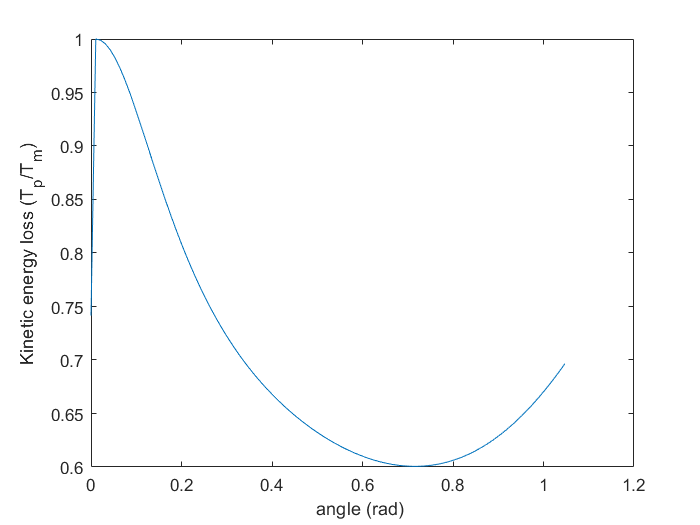


% 3) Kinetic energy ratio in function of alpha

alpha = linspace(0,pi/4,100);
q_m = zeros(3,length(alpha));
dq_m = [1; 0.2; 0];
[m1, m2, m3, l1, l2, l3, g] = set_parameters();
Perc = [];

for i = 1:length(alpha)
q_m_tmp = [alpha(i); -alpha(i); 0];
q_m = [q_m q_m_tmp];
[q_p_tmp, dq_p_tmp] = impact(q_m_tmp, dq_m);
q_p = [q_p q_p_tmp];
dq_p = [dq_p dq_p_tmp];

q1_m = q_m(1,i);
q2_m = q_m(2,i);
q3_m = q_m(3,i);
q1_p = q_p(1,i);
q2_p = q_p(2,i);
q3_p = q_p(3,i);

dq1_m = dq_m(1);
dq2_m = dq_m(2);
dq3_m = dq_m(3);
dq1_p = dq_p(1,i);
dq2_p = dq_p(2,i);
dq3_p = dq_p(3,i);

T_m_tmp = (m1*((dq1_m^2*l1^2*cos(q1_m)^2)/4 + (dq1_m^2*l1^2*sin(q1_m)^2)/4))/2 + (m2*((dq1_m*l1*cos(q1_m) - (dq2_m*l2*cos(q2_m))/2)^2 + (dq1_m*l1*sin(q1_m) - (dq2_m*l2*sin(q2_m))/2)^2))/2 + (m3*((dq1_m*l1*cos(q1_m) + (dq3_m*l3*cos(q3_m))/2)^2 + (dq1_m*l1*sin(q1_m) + (dq3_m*l3*sin(q3_m))/2)^2))/2;
T_p_tmp = (m1*((dq1_p^2*l1^2*cos(q1_p)^2)/4 + (dq1_p^2*l1^2*sin(q1_p)^2)/4))/2 + (m2*((dq1_p*l1*cos(q1_p) - (dq2_p*l2*cos(q2_p))/2)^2 + (dq1_p*l1*sin(q1_p) - (dq2_p*l2*sin(q2_p))/2)^2))/2 + (m3*((dq1_p*l1*cos(q1_p) + (dq3_p*l3*cos(q3_p))/2)^2 + (dq1_p*l1*sin(q1_p) + (dq3_p*l3*sin(q3_p))/2)^2))/2;

Perc = [Perc T_p_tmp/T_m_tmp];
end

figure
plot(alpha, Perc);
xlabel('angle (rad) ')
ylabel('Kinetic energy loss (T_p/T_m)')

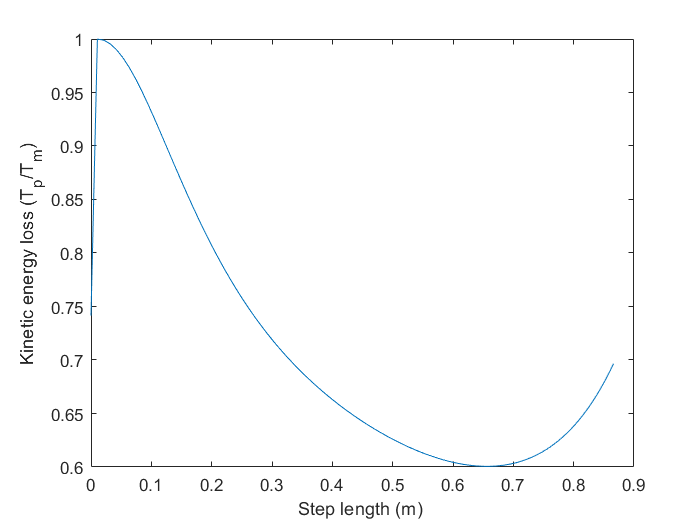


% 4) Relation between step length and energy loss

L_abs = l1*sin(alpha) + l2*sin(alpha);

figure
plot(L_abs, Perc);
xlabel('Step length (m) ')
ylabel('Kinetic energy loss (T_p/T_m)')

Finally, use the results above to complete the function impact.m in the dynamics foler.

matlabFunction(A_m, 'File', 'D:\Matlab\Leggedrobots\Prat2\three_link_biped_start\dynamics/Am_tmp.m');
matlabFunction(A_p, 'File', 'D:\Matlab\Leggedrobots\Prat2\three_link_biped_start\dynamics/Ap_tmp.m');

Remember to complete eval_A_m.m and eval_A_p.m and remove the temperory functions Am_tmp.m and A_p_tmp.m.

## Checking your impact.m function:

After completing the impact.m function, to test your code first write a function **eval_energy.m** which calculates the kinetic and potential energies of the biped given $q, \dot q$. Then use arbitrary values for $q^-$ and $\dot q^-$ and compare the kinetic and potential energies before and after impact. Clearly, you expect the total energy of the system to be smaller after impact. **Answer the following questions:** 

- What can you say about the potential energy before and after impact? 

- Try q_m = [pi/6, -pi/6, pi/10], dq_m = [1, 0.2, 0]. What percentage of the kinetic energy of the biped is lost due to the impact?  

- Plot the percentage of the kinetic energy loss due to impact as a function of angle $\alpha$ where $q^- = [\alpha, -\alpha, 0]$ and $\alpha$ varies from 0 to $\pi/4$. Assume that $\dot q^- = [1, 0.2, 0]$. **Include your plot.**

- The bigger $\alpha$ is the bigger is the step length. Based on your answer to question 3, what is the relation between step length and energy loss at impact given a fixed $\dot q^-$?   

**Your Answers:**

- **As the potential depends only on the angles, it is not changed before and after the impact.**

- **The percentage of the kinetic energy of the biped that is lost due to the impact is 0.72.**

- **See plot on the terminal.**

- **Given the relation between L and alpha, we can deduce the relation between Kinetic loss and L. See plot on the terminal.**